# **Standing wave dispersion simulation **

clear
clc

`현재 위치 설정 및 경로추가

cd 'C:\Users\PC\OneDrive\UNIST\simulation\Standing wave dispersion\STN wave dispersion 3.0 20250703'
addpath 'C:\Users\PC\OneDrive\UNIST\simulation\Standing wave dispersion\STN wave dispersion 3.0 20250703\data'

랜덤 방식 설정

rng('shuffle'); % Seed the random number generator based on the current time

vx_tilt_list = [6]

vx_tilt_list = 6

for vx_tilt_ind = 1:numel(vx_tilt_list)

기본 상수 설정

load("STN_constants.mat"); %load default constants
%you can re-define contants here!
vx_caused_tilted=vx_tilt_list(vx_tilt_ind)
z_init_vel_sigma=63.08;

vx_caused_tilted = 6

세기(I) 리스트 작성

%I1, I2 setting (I1과 I2의 행렬 크기를 같게 하세요.)

%1.2mJ
% I1_list = [0.1 0.2 0.3 0.4 0.6 1.2]*0.65;
% I2_list = [14.4 7.2 4.8 3.6 2.4 1.2]*0.65;

%1.4mJ
% I1_list = [0.1 0.2 0.4 0.5 0.7 0.8 1.4]*0.65;
% I2_list = [19.6 9.8 4.9 3.92 2.8 2.45 1.4]*0.65;

%1.6mJ
% I1_list = [0 0.1 0.2 0.25 0.4 0.8 1.6]*0.7;
% I2_list = [0 25.6 12.8 10.2 6.4 3.2 1.6]*0.7;

%SW
I1_list = [0:0.05:5];
I2_list = [0:0.05:5];

% off 
% I1_list = [0];
% I2_list = [0];
Cell_velocity=cell(numel(I2_list),1);

Trajectory calculation.

for I_ind = 1:numel(I2_list)
run('Main_code.m') %Main code returns the velocity of x,y,z
% run('Main_code_CUDA.m') %Main code returns the velocity of x,y,z
Cell_velocity{I_ind}=velocity;% Cell_velocity(intensity list) = velocity of particle, 
end

Elapsed time is 8.292052 seconds.
Elapsed time is 10.140051 seconds.
Elapsed time is 9.501706 seconds.
Elapsed time is 9.433235 seconds.
Elapsed time is 9.396020 seconds.
Elapsed time is 10.416582 seconds.
Elapsed time is 9.605888 seconds.
Elapsed time is 9.505567 seconds.
Elapsed time is 9.564994 seconds.
Elapsed time is 9.680613 seconds.
Elapsed time is 9.961885 seconds.
Elapsed time is 10.498149 seconds.
Elapsed time is 9.669938 seconds.
Elapsed time is 9.894214 seconds.
Elapsed time is 9.853877 seconds.
Elapsed time is 9.760554 seconds.
Elapsed time is 9.862678 seconds.
Elapsed time is 10.115149 seconds.
Elapsed time is 10.523568 seconds.
Elapsed time is 10.152173 seconds.
Elapsed time is 10.136874 seconds.
Elapsed time is 10.066449 seconds.
Elapsed time is 9.809755 seconds.
Elapsed time is 10.494726 seconds.
Elapsed time is 10.691626 seconds.
Elapsed time is 11.483650 seconds.
Elapsed time is 9.937851 seconds.
Elapsed time is 9.958350 seconds.
Elapsed time is 9.979434 seconds.
Ela

Image blurring 상수 설정

vel_pix=2.28; %픽셀당 속도
rep_std=4.0; %electron repulsion standard deviation
rep_vel=2.7; %electron repulsion speed standard deviation

Image blurring (z축 방향으로는 계산안함)

run('Image_code_voigt.m')

plotting

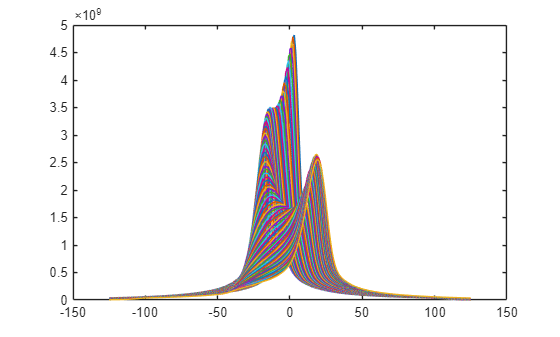

plot(xgrid,sumx)

Save

%making the data saved
constants = struct();
constants.I1_list = I1_list;
constants.I2_list = I2_list;
constants.lambda = lambda;
constants.MAX = MAX;
constants.tend = tend;
constants.tstep = tstep;
constants.vx_caused_tilted = vx_caused_tilted;
constants.vel_pix=vel_pix;
constants.Dye_sigma=Dye_sigma;
constants.w0z = w0z;
constants.w0y = w0y;
constants.jm_data  = jm_data;
% constants.x_init_distribution = x_init_distribution;
constants.x_init_vel_sigma= x_init_vel_sigma;
constants.y_init_vel_sigma= y_init_vel_sigma; 
constants.z_init_vel_sigma = z_init_vel_sigma;
constants.z_init_vel_off = z_init_vel_off;
constants.Dye_tau=Dye_tau;
constants.Ips_z = Ips_z;
constants.Ips_y = Ips_y;
constants.Ij_distribution = Ij_distribution;

data = struct();
data.xgrid=xgrid';
data.ygrid=ygrid';
data.img_matrix=img_matrix;
data.sumx=sumx;
data.sumy=sumy;

filename=sprintf("data_SW_20251202_%2.0f.mat",vx_tilt_ind)

save(filename,'data','I1_list','I2_list','Cell_velocity','constants');

filename = "data_SW_20251202_ 1.mat"

end